%f = 40
f = 2130

f = 2130

w = 2 * pi * f;
T = 1/f

T = 4.6948e-04

mm = 1000

mm = 1000


point_distance = 0.01; %in m

c = 343.3 %in m/s

c = 343.3000

loss_per_distance = -3 % in dB

loss_per_distance = -3


lambda = c / f % in m

lambda = 0.1612


k = 2 * pi / lambda

k = 38.9839


N_hor = 600;
N_ver = N_hor;

array_length_m = 1210 / mm

array_length_m = 1.2100

array_length = round(array_length_m / point_distance)

array_length = 121

No_linearray_elements = 6

No_linearray_elements = 6

points_per_element = round(array_length / No_linearray_elements);
array_start = round((N_ver - array_length) / 2);
array_end = round((N_ver + array_length) / 2);

total_phase_shift_deg = 420;
total_phase_shift_rad = total_phase_shift_deg * pi/180;
t_start = 0

t_start = 0

t_end = 0.002

t_end = 0.0020

%t_end = total_phase_shift_rad / w
total_phase_shift = (t_end - t_start) * w

total_phase_shift = 26.7664


array_frequency = c / array_length_m

array_frequency = 283.7190

ratio_arrarylenth_lambda = array_length_m / lambda

ratio_arrarylenth_lambda = 7.5074

ratio_arraryelementlenth_lambda = array_length_m / No_linearray_elements / lambda

ratio_arraryelementlenth_lambda = 1.2512

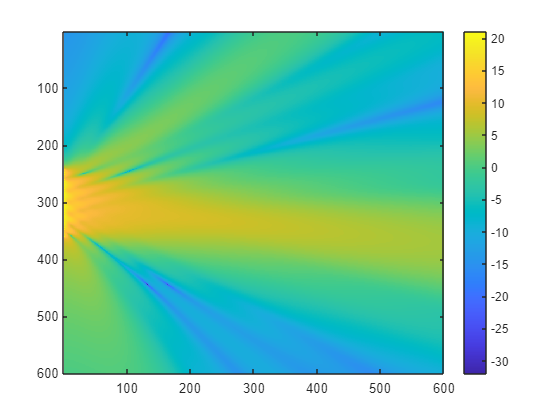


d_t = (t_end - t_start) / (No_linearray_elements - 1);

pressure_field = zeros(N_hor, N_ver);
delay_times = zeros(N_ver, 1);
gains = zeros(N_ver, 1);


for a = 1:1:No_linearray_elements
    gain = exp(-((a - 3.5)/2.5)^4);
    %gain = 1.;
    for dy = 1:1:points_per_element
        delay_times((a - 1) * points_per_element + dy + array_start) = (a - 1) * d_t;
        gains((a - 1) * points_per_element + dy + array_start) = gain;
    end
end


for y = 1:1:N_ver
    for x = 1:1:N_hor
        pressure = 0;
        for source = array_start:4:array_end
            delta_x = x - 1;
            delta_y = y - source;
            distance = sqrt(delta_x^2 + delta_y^2) * point_distance;
            time = delay_times(source,1);
            pressure = pressure + gains(source,1) * exp(1i * (w * time - distance * k)) / distance;
        end
        pressure_field(y,x) = 10 * log10(abs(pressure));
    end
end

imagesc(pressure_field)
colorbar


%imagesc(spl_field)
%colorbar